- 시간 커팅 OK

- 값들만 나오면 됨 OK

- 데이터 포맷 한줄 OK

- 필터링 선택 스위치 OK

- plot을 위해서 main이 아닌 부위는 폭을 줄이기

- plot 에서 데이터 테이블로 뺴기

- SNR standard한 공식 log ....

- peak to peak

- mean rms

4월 27일

- enveloping 옵션 - 코드에서 rms와 peak 선택할 수 있도록 OK 

- peak2peak 개선: `peak 중 입력한 threshold 값보다 큰 것만 가져옴 `OK

- mean rms: rectify 한 다음에 그 신호들의 평균값 산술평균. 시간범위 선택할 수 있어야 함. 오브젝트에서 획정한 시간 구간 내에서도 더 세밀하게 구간 나눠서 볼 수 있어야 함 OK

- signal to noise ratio: signal 구간의 rms / resting 구간의 rms OK

- heatmap 숫자 표시 옵션 OK

- heatmap 속도 OKß

# Part 1. Preview on single channel

mapping 하기 전에, 채널 하나에 대해서 전처리 과정이 어떻게 진행되는지 보겠습니다. 보내주신 week별로 정리된 파일을 사용하겠습니다.

## 1.데이터 읽어오기

보내주신 vertical 형식의 데이터를 읽어옵니다. 기존의 데이터와 다른 포맷이기 때문에 기존의 로딩 함수를 사용하지 않고 직접 channel object를 만듭니다.

**resampling.**

코드를 보면 t를 등간격으로 만들기 위해 spline을 써서 resampling을 하는데, 이는 spike detection 알고리즘이 등간격을 가정하기 때문입니다.

데이터가 거의 등간격으로 수집되지만, 약간의 오차가 있기 때문에 resampling이 필요합니다. 오차가 아주 작기 때문에 signal 모양에는 변화가 거의 없습니다.

**channel object.**

channel object는 읽어온 데이터를 저장하고 처리하는 단위입니다. 데이터를 순차적으로 변형하기 때문에 각 단계의 데이터를 한 곳에 모아두기 위해 object로 관리하는 것입니다.

channel object가 생성되면 기본적인 정보가 프린트됩니다.

파라미터:

- signal 벡터

- time 벡터

- sampling frequency

- organoid number

- channel number

- month number

마지막 파라이터 3개는 관리를 위해 사용자가 임의로 지정하는 번호이고, 데이터의 내용을 반영하지 않습니다.

저는 month number에 week number를 써 주었습니다.

raw_data = readmatrix("/Users/mac/GitHub/neurosignal-matlab/data/Z1-1.xlsx"); %데이터 파일 읽어올 떄는 파일 경로를 다 써줍니다.

size_of_data = size(raw_data); % 데이터 행과 열 개수
number_of_timestamp = size_of_data(1)-1; % 열 개수 - 1 = 측정 timestamp 개수
number_of_channel = size_of_data(2)-1; % 행 개수 - 1 = 채널 개수

%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(:,1); %시간 벡터를 따로 저장
sampleRateUsed = number_of_timestamp/(tVector(end) - tVector(1)); %sample rate 계산. 전체 시간을 관측치 개수로 나눔


%%%%%%
%원하는 컬럼을 지정해서 한개의 week만 불러옴
channelNum = 3;
xVector = raw_data(:,channelNum+1); % i번째 채널 데이터는 1+1번째 행에 있음 %결국엔 여기서 몇번째 컬럼인지를 기술해 주면 됩니다.
xVector = xVector(~isnan(xVector)); % time 열에 맞춰 데이터를 불러오기 때문에, 빈칸이 NaN으로 들어옵니다. 이 부분을 제거해 줍니다.


%%%%%%%%%%%


% 주신 파일에서 시간 구간이 week마다 다르기 때문에, signal 길이에 맞게 t vector를 잘라 줍니다
tVector = tVector(1:length(xVector));

[xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
                                                    %organoid, channelNum,
                 % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
emg = channel(xResampled, tResampled, sampleRateUsed, 1, channelNum, 3);

channel number = 3
sampling rate = 1017.251797Hz
starts at 0.000000, ends at 38.880246, duration = 38.880246
number of timestamps = 39552



## 2. 시간 구간 자르기

cutTime method에 시간 구간을 array로 넣어 줍니다. 아래 코드에서는 10초 - 30초 구간만 남기고 나머지를 버립니다.

cutTime은 다른 모든 작업보다 먼저 해 주시기 바랍니다.

만약 작업을 하다가 시간 구간을 바꿔야 할 경우 위 섹션의 코드를 재실행하여 데이터를 다시 불러온 다음 cutTime을 한 다음에 다른 작업을 진행해 주시기 바랍니다. 다른 작업을 한 다음에 cutTime을 하면 코드가 꼬입니다.

emg.cutTime([10,30]) %여기 있는 숫자를 바꾸면 자르는 구간을 변경할 수 있음

## 3. 전처리

전처리시 모든 과정과 유형의 데이터가 따로 저장됩니다.

필터링 등을 하지 않더라도, 일단 4단계의 전처리를 모두 쭉 진행해 주시기 바랍니다. 모든 전처리를 다 하는 것을 전제로 코드가 작성되어 있습니다.

channel object 이름(이 예제에서는 `emg`) 뒤에 .을 붙이고 아래 변수명을 붙이면 해당 데이터를 array 형태로 얻을 수 있습니다.

**time data(x축)**

- `.t`

**signal data(y축)**

#### 1,2단계  filtering

- `.raw : `baseline filtering, butterworth filtering 둘 다 안함

- `.filtered` : baseline filtering 하지 않고, butterworth filtering은 함

- `.signalRawLowBaseline` : baseline filtering하고, butterworth filtering은 안함

- `.signalRawNoBaseline` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering은 안함

- `.signalFilteredLowBaseline` :  baseline filtering하고, butterworth filtering 함

- `.signalFilteredNoBaseline` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering 함

####         3단계 Rectified

- `.rawRectified` : baseline filtering, butterworth filtering 둘 다 안함

- `.filteredRectified` : baseline filtering 하지 않고, butterworth filtering은 함

- `.signalRawLowBaselineRectified`: baseline filtering하고, butterworth filtering은 안함

- `.signalRawNoBaselineRectified` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering은 안함

- `.signalFilteredLowBaselineRectified` : baseline filtering하고, butterworth filtering 함

- `.signalFilteredNoBaselineRectified` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering 함

####         4단계 enveloping 처리 이후

- `.rawEnveloped` : baseline filtering, butterworth filtering 둘 다 안함

- `.filteredEnveloped` : baseline filtering 하지 않고, butterworth filtering은 함

- `.signalRawLowBaselineEnveloped` : baseline filtering하고, butterworth filtering은 안함

- `.signalRawNoBaselineEnveloped` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering은 안함

- `.signalFilteredLowBaselineEnveloped` : baseline filtering하고, butterworth filtering 함

- `.signalFilteredNoBaselineEnveloped` : baseline filtering해서 baseline 부분 0으로 만들고, butterworth filtering 함

#### 2.1. baseline filtering

 baseline 부분을 필터링하여 진폭을 줄입니다.

parameter는 2개입니다.

- baseline 시간 구간들을 cell of array로 넣어 줍니다. **초 단위. 원래 시간 베이스로.**

- basline 구간에서 어떤 범위로 필터링할지 **Hz** 범위를 array로 넣어 줍니다. 데이터에 따라 적절한 값이 다른 것으로 보입니다.  high보다는 low 값을 조절하는 것이 모양이 잘 변합니다.

emg.filterBaseline( { [15,20], [25,30] }     , [250,1000] )

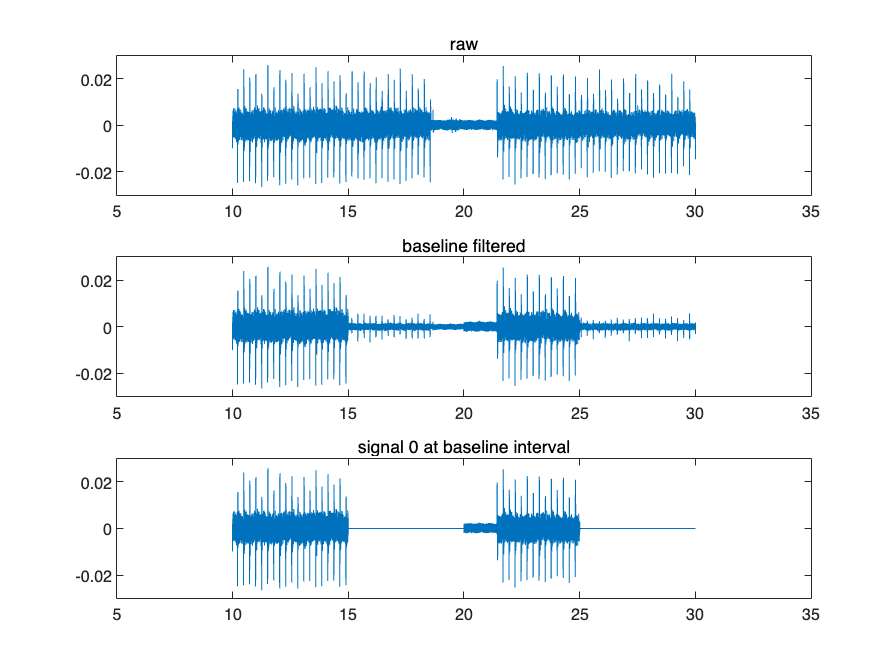


figure;
subplot(3,1,1);
plot(emg.t,emg.raw);
title("raw")
ylim([-0.03, 0.03])

subplot(3,1,2);
plot(emg.t,emg.signalRawLowBaseline)
title("baseline filtered")
ylim([-0.03, 0.03])

subplot(3,1,3);
plot(emg.t,emg.signalRawNoBaseline)
title("signal 0 at baseline interval")
ylim([-0.03, 0.03])        

#### 2.2. filtering

 Reference에 있는 대로 butterworth filter를 highpass와 notch로 걸어 주었는데, notch filter는 reference에 나온 데로 5th order로 하면 결과가 이상하게 나와서 2nd order로 하였습니다.

60hz를 필터링하기 위해 [59, 61] 구간을 제거하도록 하였습니다.

filtering을 적용하여도 filtering이 적용되지 않은 데이터가 그대로 저장되어 있습니다. 또한 현재 코드 구성상 filtering을 해야 다음 스텝으로 넘어갈 수 있기 때문에, filtering을 하지 않으신다고 해도 일단 filtering을 하시기 바랍니다.

파라미터:

highPassButterworth:

- 첫 번째 파라미터는 order

- 두 번째는 cutoff frequency

notchButterworth

- 첫 번째 파라미터는 order

- 두 번째는 제거할 범위

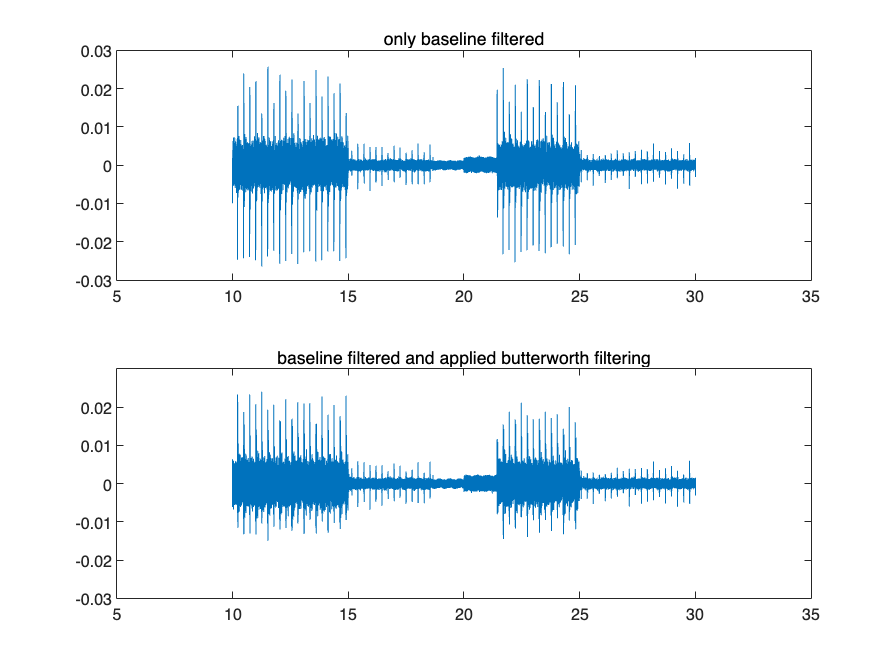

%                      order, cutoff frequency(Hz)
emg.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz

%                  order, cutoff frequency(Hz)interval
emg.notchButterworth(2, [49,51]) % 2th order Butterworth notch filter to reduce the noise at 50 Hz.

figure;
subplot(2,1,1);
plot(emg.t,emg.signalRawLowBaseline);
title("only baseline filtered")
ylim([-0.03, 0.03])

subplot(2,1,2);
plot(emg.t,emg.signalFilteredLowBaseline)
title("baseline filtered and applied butterworth filtering")
ylim([-0.03, 0.03])

#### 3. rectification

rectification은 단지 신호값에 절댓값을 취하는 것에 불과하므로, 별도의 parameter를 입력할 필요가 없습니다.

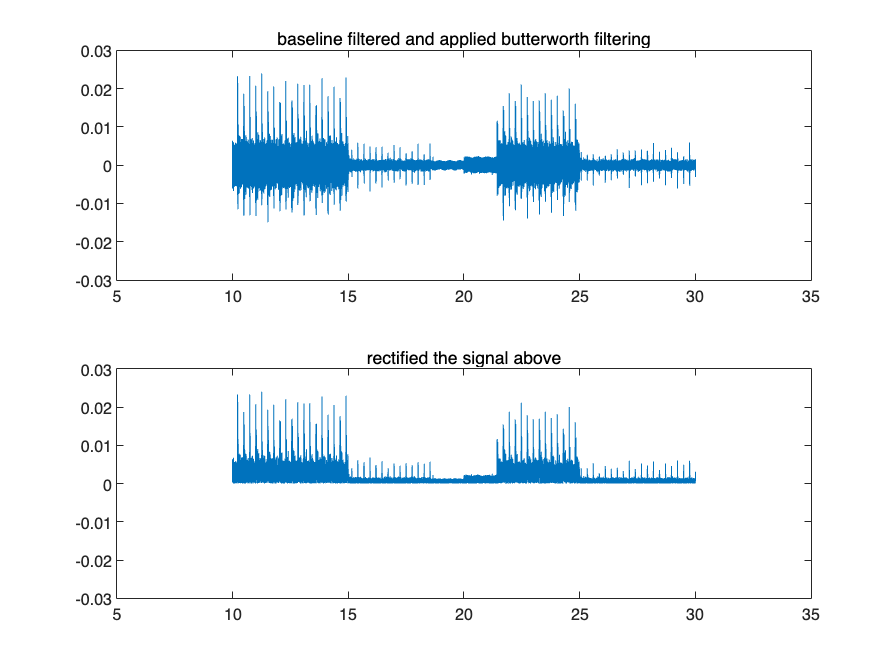

emg.rectify();

figure;
subplot(2,1,1);
plot(emg.t,emg.signalFilteredLowBaseline)
title("baseline filtered and applied butterworth filtering")
ylim([-0.03, 0.03])

subplot(2,1,2);
plot(emg.t,emg.signalFilteredLowBaselineRectified)
title("rectified the signal above")
ylim([-0.03, 0.03])

6가지 종류 코멘트로 넣기

#### 4. enveloping(normalization)

matlab signal processing toolbox 설치가 필요합니다.

[https://kr.mathworks.com/help/signal/ref/envelope.html](https://kr.mathworks.com/help/signal/ref/envelope.html)

위의 함수를 사용하였습니다. RMS와 peak method에 대한 설명이 위 페이지에 서술되어 있습니다.

파라미터:

- 첫번째:  smoothness paramter. RMS냐 peak이냐에 따라 정확한 의미는 다르지만, 값이 높을수록 더 부드러운 곡선이 나옵니다.

- 두번째: enveloping metod. "rms", "peak", "analytic" 중 하나를 입력합니다.

아래 그림을 보면 RMS로 enveloping시 진폭이 줄어듭니다. 이는 enveloping 전 signal에 높은 spike가 여럿 있었지만 높이가 낮은 부분도 많았기 때문일 수 있습니다. RMS는 mean을 취하기 때문입니다.


figure;
subplot(4,1,1);
plot(emg.t,emg.signalFilteredLowBaselineRectified)
title("baseline filtered, applied butterworth filtering, rectified")
ylim([-0.03, 0.03])

subplot(4,1,2);
emg.envelope(200, "rms") % 
plot(emg.t,emg.signalFilteredLowBaselineEnveloped)
title("enveloped the signal above, with RMS method of smoothness parameter 200")
ylim([-0.03, 0.03])
xlim([5,35])

subplot(4,1,3);
emg.envelope(100, "peak") % 필터 길이 = 150
plot(emg.t,emg.signalFilteredLowBaselineEnveloped)
title("enveloped the signal above, with peak method of smoothness parameter 100")
ylim([-0.03, 0.03])
xlim([5,35])

subplot(4,1,4);
emg.envelope(200, "peak") % 필터 길이 = 150
plot(emg.t,emg.signalFilteredLowBaselineEnveloped)
title("enveloped the signal above, with peak method of smoothness parameter 200")
ylim([-0.03, 0.03])
xlim([5,35])

## 3. 요약값

              %시간 변수

        t

        originalTime

        originalSignal

        cutTime도 하기 전의 데이터

        %전처리 거치지 않은 signal

        raw

        % baseline filterd

        signalRawLowBaseline

        signalRawNoBaseline

        signalFilteredLowBaseline

        signalFilteredNoBaseline

        %baseline filtering 안하고, butterworth filtering만 한 signal, rectify

        %하기 전

        filtered

        % Rectified

        rawRectified

        filteredRectified

        signalRawLowBaselineRectified

        signalRawNoBaselineRectified

        signalFilteredLowBaselineRectified

        signalFilteredNoBaselineRectified

        % Enveloped

        rawEnveloped

        filteredEnveloped

        signalRawLowBaselineEnveloped

        signalRawNoBaselineEnveloped

        signalFilteredLowBaselineEnveloped

        signalFilteredNoBaselineEnveloped

모든 계산은 baseline filtering이나 butterworth filtering 거치지 않은 raw 데이터를 가지고 함.  

#### 3.1. peak to peak 

`상황:`

- `raw data를 가지고 계산한다.`

- `baeseline 부분의 정보는 무시한다. 그러나 baseline 구간의 위치를 정확히 특정할 수 없다.`

`해결법:`

- `일단 raw data를 plot해 본다.`

- `연구자가 적절한 threshold 값을 결정한다. `

- `해당 threshold보다 절댓값이 큰 peak만 센다.`

`matlab의 findpeaks 함수를 사용합니다.`

`https://kr.mathworks.com/help/signal/ref/findpeaks.html`

`이 함수는 local maximum의 위치와 값을 찾습니다.`

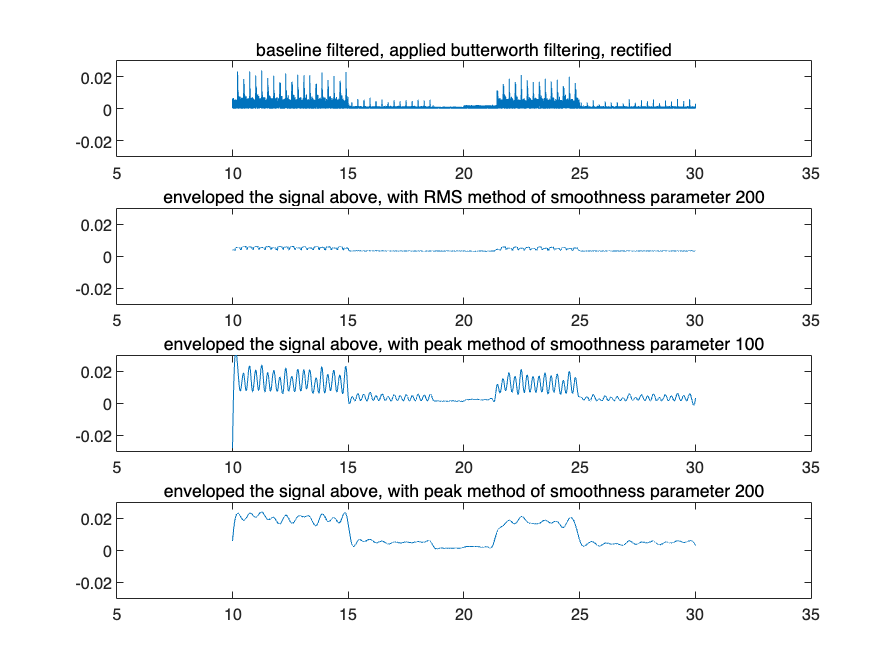

figure; % 이걸 선언해 주어야 다른 figure와 구분됨

     %x축 데이터            y축 데이터             

subplot(2, 1, 1)
plot(emg.originalTime,  emg.originalSignal)
title("raw data, before cutTime")

**파라미터**

- 시간 변수 데이터(x축 데이터)

- signal 데이터(y축 데이터)

- threshold 값(양수): 이 값보다 절댓값이 큰 극댓값, 극솟값만 peak로 간주

[meanPeakToPeak, localMaxValueSelected, localMaxLocSelected, localMinValueSelected, localMinLocSelected] = meanLocalPeakToPeak(emg.originalTime, emg.originalSignal, 0.02);
meanPeakToPeak
subplot(2,1,2)
hold on; %여러 그래프 겹쳐 그리기
plot(emg.originalTime,  emg.originalSignal)
plot(localMaxLocSelected,localMaxValueSelected, "bo") % local max value 위치 표시
plot(localMinLocSelected,localMinValueSelected, "bo") % local min value 위치 표시

title("raw data, before cutTime, with peaks")
hold off % 겹쳐 그리기 끝

meanPeakToPeak = 0.0458

#### 3.2. Mean RMS

계산 방법

- 지정한 구간 내에서

- 신호의 절댓값의

- 산술평균

지정한 구간은 cutTime으로 자른 구간 이내여야 합니다. cutTime으로 자른 구간 밖의 signal까지 포함하려면, cutTime을 다시 하거나 아니면 같은 원본 데이터로 또 다른 channel object를 추가로 만드는 것을 추천합니다.

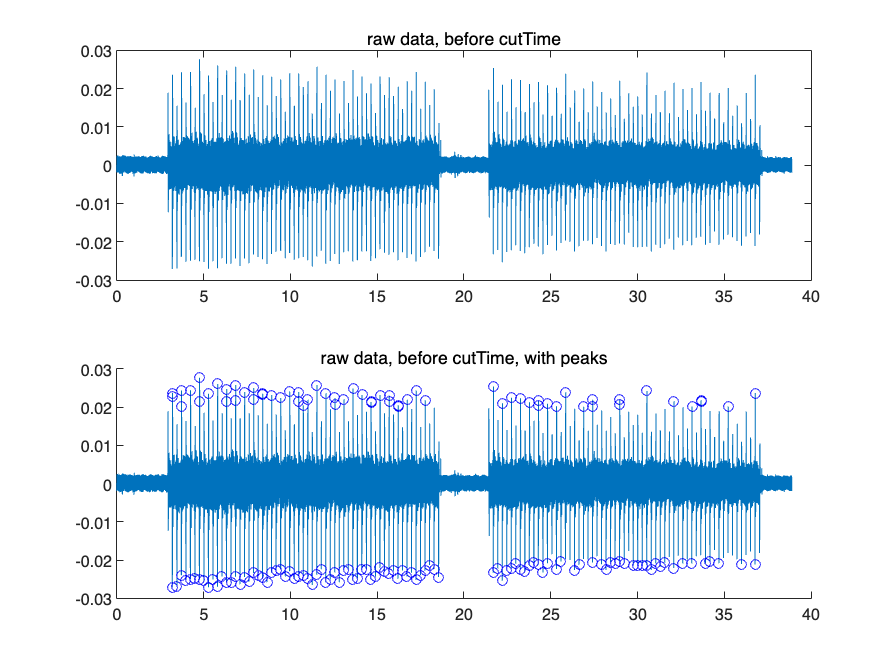

ans = 0.0067

ans = 0.0070

%week 2 채널 object 다시 만들기
xVector = raw_data(:,4); % week2 데이터는 4번째 행에 있음 %결국엔 여기서 몇번째 컬럼인지를 기술해 주면 됩니다.
xVector = xVector(~isnan(xVector)); % time 열에 맞춰 데이터를 불러오기 때문에, 빈칸이 NaN으로 들어옵니다. 이 부분을 제거해 줍니다.


% 주신 파일에서 시간 구간이 week마다 다르기 때문에, signal 길이에 맞게 t vector를 잘라 줍니다
tVector = tVector(1:length(xVector));


[xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
                                                    %organoid, channelNum,
                       % 마지막 3개는 단순히 관리를 위한 번호: organoid number, channel number, month number
week2_for_summary = channel(xResampled, tResampled, sampleRateUsed, 1, 1, 2);

resting 구간을 더 많이 포함한 meanRMS가 더 작게 나옴

week2_for_summary.meanRMS( { [12, 15], [25, 30] } ) %가운데 resting 구간 포함 안함
week2_for_summary.meanRMS( { [12, 20], [25, 30] } ) %가운데 resting 구간 절반 포함
week2_for_summary.meanRMS( { [12, 23], [25, 30] } ) %가운데 resting 구간 모두 포함

#### 3.3.  signal to noise ratio

계산 방법 (RMS 계산은 signal processing toolbox의 `rms() `함수 사용)

- Psignal = signal 구간의 RMS 값

- Pnoise = noise 구간의 RMS 값

- return k * log(Psignal / Pnoise)

- k값과 log의 밑은 여러 문서에서 다르게 정의하고 있어서, 함수의 parameter로 두지 않고 밖으로 뺌

matlab 로그 함수(https://kr.mathworks.com/help/matlab/exponents-and-logarithms.html)

- `log`

- `log2`

- `log10`

**파라미터**

- **signal intervals**

- **noise intervals**

[pSignal, pNoise] = week2_for_summary.SNRValue({[5,15], [25,35]},{[0,2], [17,22]})
10 * log2(pSignal/pNoise)

# Part 2. pixel mapping

EMG 데이터에 맞는 기능을 구현하기 위해, firing rate heatmap을 만드는  `timeVaryingHeatmap ``클래스를 수정하여 ``timeVaryingHeatmapEMG 클래스를 ``만들었습니다.`

`먼저 아래 코드로 ``timeVaryingHeatmapEMG ``오브젝트를 하나 만듭니다. 여기에 각 channel object를 넣고 전처리를 한 다음 heatmap을 그릴 것입니다.`

%                      nrow, ncol
ani = timeVaryingHeatmapEMG(5,5); % timeVaryingHeatmap 오브젝트 생성. pixel들이 5*5 배열로 되어 있다고 가정.

**rms 말고 peak로**

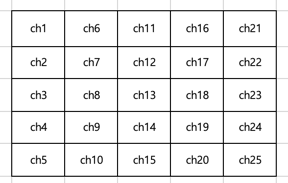

raw_data = readmatrix("./data/2D mapping raw data(원본).xlsx");

channel number = 1
sampling rate = 1017.251797Hz
starts at 0.000000, ends at 38.880246, duration = 38.880246
number of timestamps = 39552




size_of_data = size(raw_data); % 데이터 행과 열 개수

ans = 0.0024

number_of_timestamp = size_of_data(1)-1; % 열 개수 - 1 = 측정 timestamp 개수

ans = 0.0020

number_of_channel = size_of_data(2)-1; % 행 개수 - 1 = 채널 개수

ans = 0.0018


%시간 벡터 저장 및 sampling frequency 계산
tVector = raw_data(:,1); %시간 벡터를 따로 저장
sampleRateUsed = number_of_timestamp/(tVector(end) - tVector(1)) %sample rate 계산. 전체 시간을 관측치 개수로 나눔

for i = 1 : number_of_channel %각 채널별로
    channelNum = i;
    column_number = fix((i-1)/5) + 1; %5로 나눈 몫 + 1이 column 번호

    row_number = rem(i,5); % 5로 나눈 나머지가 row 번호.
    if row_number == 0 %나머지가 0이면 row number = 5

pSignal = 0.0052

pNoise = 0.0031

pSignal = 0.0052

pNoise = 0.0031

        row_number = 5;

ans = 7.4568

    end

    xVector = raw_data(:,i+1); % i번째 채널 데이터는 i+1번째 행에 있음
    [xResampled, tResampled] = resample(xVector, tVector, sampleRateUsed, 'spline'); %시간간격을 등간격으로 resample 및 interpolation 실행
                                                                %
    channel_now = channel(xResampled, tResampled, sampleRateUsed, 1, channelNum, 1);
    %  이 pixel의 row번호, column번호, pixel에 mapping할 channel 번호
    ani.addPixel(row_number, column_number, channel_now );
end

일괄 전처리

####  1. 시간 구간 자르기

ani.cutTime([0.1, 2.5])

#### 2. baseline filtering

ani.filterBaseline({[0.5,0.8], [1.6,2]},[200,1000])

#### 3. filtering

ani.highPassButterworth(3, 30) % 3rd order Butterworth high pass filter at 30 Hz
ani.notchButterworth(2, [59,61]) % 2th order Butterworth notch filter to reduce the noise at 60 Hz.


#### 4. rectify

ani.rectify()

#### 5. normalize

ani.envelope(150, "peak")

sampleRateUsed = 2.4414e+04

heatmap 그리기

첫 번째 파라미터는 시간 간격입니다. 밀리세컨드 단위로 입력합니다.

두 번째 파라미터는 true/false로 filtered data를 사용할지, filtering하지 않은 데이터를 사용할지(rectify, normalize는 적용된 상태)를 결정합니다.

세 번째 파라미터는 heatmap의 colormap입니다. [https://kr.mathworks.com/help/matlab/ref/colormap.html#buq1hym](https://kr.mathworks.com/help/matlab/ref/colormap.html#buq1hym) 에서 colormap 목록을 확인할 수 있습니다.

아래 탐색 막대에서 배속을 조절할 수 있습니다. 배속 조절 버튼 옆의 버튼을 누르면 mp4 파일로 저장할 수도 있습니다.                           

ani.makeTimeVaryingHeatmap( ...
    50, ... % 시간 간격(millisecond)
    "raw", ... %datatype
    true, ... % display number or not
    cool, ... %colormap
        "test.mp4" ) 


channel number = 1
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 1)th slot, added channel 1 


channel number = 2
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 1)th slot, added channel 2 


channel number = 3
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 1)th slot, added channel 3 


channel number = 4
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 1)th slot, added channel 4 


channel number = 5
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 1)th slot, added channel 5 


channel number = 6
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 2)th slot, added channel 6 


channel number = 7
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 2)th slot, added channel 7 


channel number = 8
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 2)th slot, added channel 8 


channel number = 9
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 2)th slot, added channel 9 


channel number = 10
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 2)th slot, added channel 10 


channel number = 11
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 3)th slot, added channel 11 


channel number = 12
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 3)th slot, added channel 12 


channel number = 13
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 3)th slot, added channel 13 


channel number = 14
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 3)th slot, added channel 14 


channel number = 15
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 3)th slot, added channel 15 


channel number = 16
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 4)th slot, added channel 16 


channel number = 17
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 4)th slot, added channel 17 


channel number = 18
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 4)th slot, added channel 18 


channel number = 19
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 4)th slot, added channel 19 


channel number = 20
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 4)th slot, added channel 20 


channel number = 21
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (1, 5)th slot, added channel 21 


channel number = 22
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (2, 5)th slot, added channel 22 


channel number = 23
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (3, 5)th slot, added channel 23 


channel number = 24
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (4, 5)th slot, added channel 24 


channel number = 25
sampling rate = 24414.063998Hz
starts at 0.000000, ends at 2.606940, duration = 2.606940
number of timestamps = 63647




 In the (5, 5)th slot, added channel 25 


ani.makeTimeVaryingHeatmap( ...


cutting the time of (1, 1)th element = channel 1
Reset all preprocessing of signalsnew startTime = 0.099983
new endTime = 2.500034
new duration = 2.400051
new nTimestamp = 58596

cutting the time of (1, 2)th element = channel 6
Reset all preprocessing of signalsnew startTime = 0.099983
new endTime = 2.500034
new duration = 2.400051
new nTimestamp = 58596

cutting the time of (1, 3)th element = channel 11
Reset all preprocessing of signalsnew startTime = 0.099983
new endTime = 2.500034
new duration = 2.400051
new nTimestamp = 58596

cutting the time of (1, 4)th element = channel 16
Reset all preprocessing of signalsnew startTime = 0.099983
new endTime = 2.500034
new duration = 2.400051
new nTimestamp = 58596

cutting the time of (1, 5)th element = channel 21
Reset all preprocessing of signalsnew startTime = 0.099983
new endTime = 2.500034
new duration = 2.400051
new nTimestamp = 58596

cutting the time of (2, 1)th element = channel 2
Reset all preprocessing of signalsnew startTime = 0.

    100, ... % 시간 간격(millisecond)
    "filtered", ... %datatype
    false, ... % display number or not
    spring, ...  %colormap
    "test2.mp4")
    

# 그래프 그리기 & 데이터 뽑기 

### 그려진 그래프 편집하기

- 그래프를 한번 클릭하면 상단 툴바 '삽입' 옆에 'figure' 메뉴가 생김. 해당 메뉴에서 그래프의 여러 요소를 수정할 수 있음

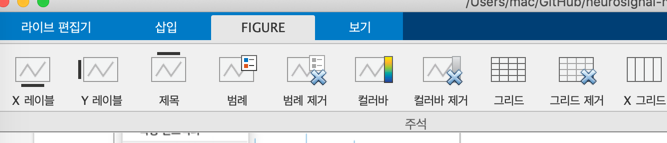

-  그래프 위에 커서를 가져다 대면 우측 상단에 나오는 화살표 버튼을 누르면 figure 편집 창이 나옴. 여기서도 그래프를 수정할 수 있음

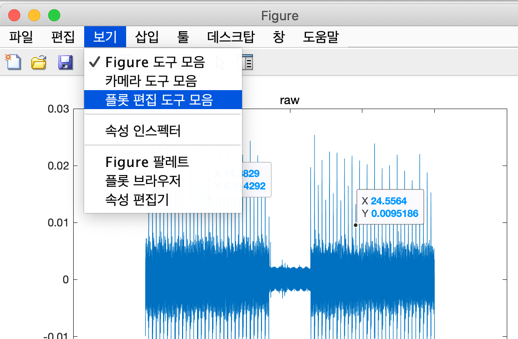

- 그래프에 선이나 점이 그려진 부분 위에 커서를 가져가면 우측 상단에 5개의 아이콘이 나오는데, 맨 왼쪽 버튼을 이용해 그래프를 이미지 파일이나 벡터 그래픽으로 저장할 수 있음

              

### 3.1. raw signal plot

(cutTime만 적용된 상태)

- x축 데이터: `.t`

- y축 데이터: `.raw`

figure;
plot(emg.t,emg.raw);
title("raw")
ylim([-0.03, 0.03])

maxRaw = 0.6426

maxFiltered = 0.3891

maxSignalRawLowBaseline = 0.6426

maxSignalRawNoBaseline = 0.6426

maxSignalFilteredLowBaseline = 0.4051

maxSignalFilteredNoBaseline = 0.4051

**3.1.1. Figure data export basics(line graph)**

Matlab의 figure의 구조는 아래와 같습니다. 

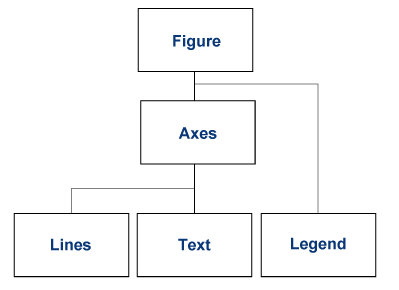

axes하나가 그래프 하나를 의미합니다. 위 figure의 경우 axes 하나만 있습니다.

ax = gca; % get current axes
h = findobj(gca,'Type','line');
x = h.XData; 
y = h.YData;

row vector 형식으로 나오기 때문에 transpose를 취합니다. 변수명을 array 이름으로 해서 저장합니다.

datatype = raw
step size = 1221 timestamps = 50.012157 miliseconds
Total 47 steps
length = 2.400051e+00 seconds
realtime framerate per second = 1200 
max signal value = 0.747351, ColorLimits is set w.r.t this value.

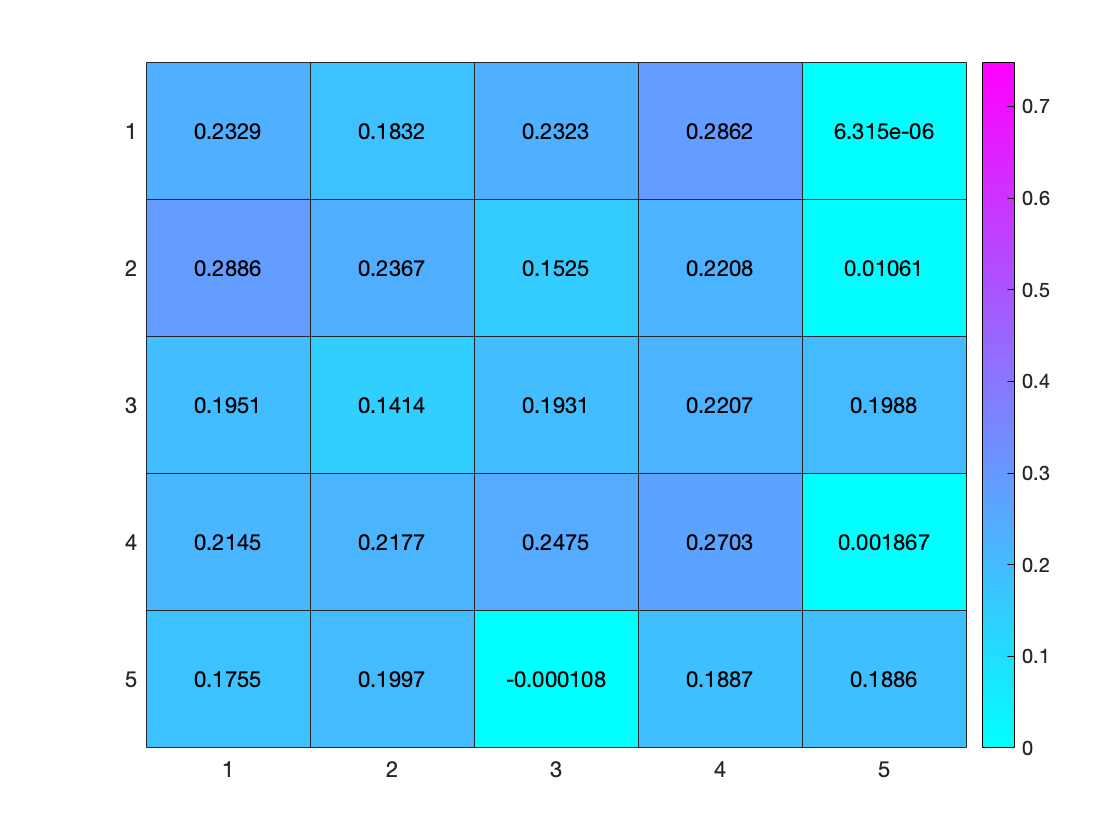

time = x'
raw_signal = y'

엑셀 파일로 뽑기 위해 table 오브젝트를 만듭니다. array도 엑셀로 뽑을 수 있지만, table이 열 이름을 지정하기가 더 편합니다. column array를 input으로 넣으면 자동으로 array 이름을 열 이름으로 정합니다.

datatype = filtered
step size = 2441 timestamps = 99.983354 miliseconds
Total 24 steps
length = 2.400051e+00 seconds
realtime framerate per second = 600 
max signal value = 0.437711, ColorLimits is set w.r.t this value.

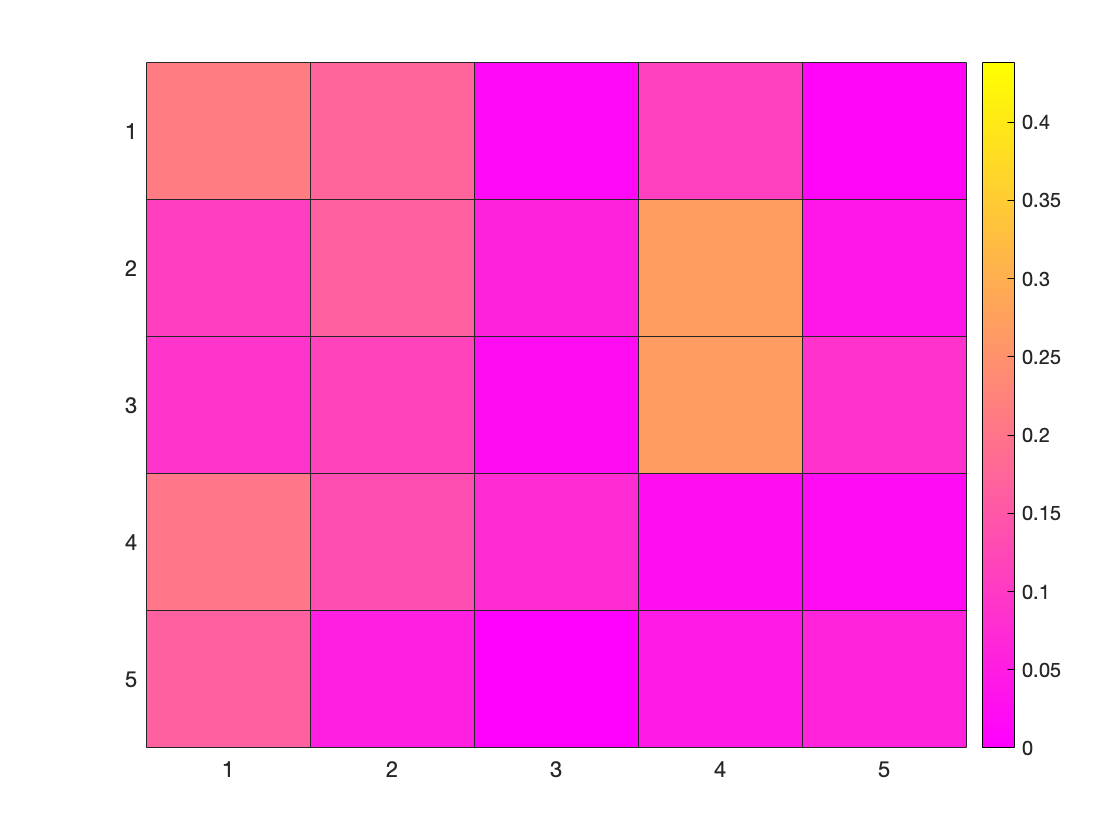

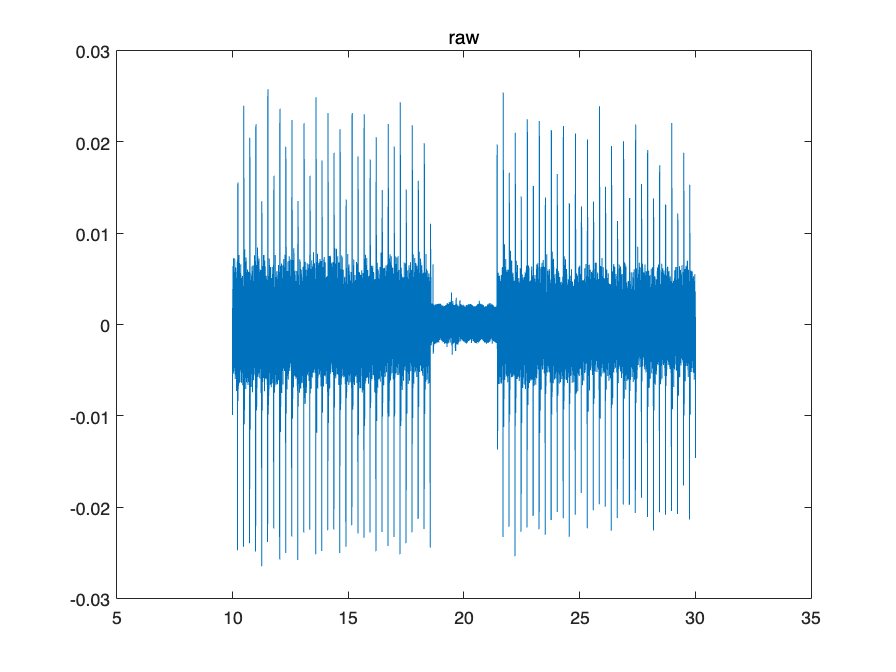

time =     9.9995
   10.0005
   10.0015
   10.0024
   10.0034
   10.0044
   10.0054
   10.0064
   10.0074
   10.0083


raw_signal =    -0.0065
   -0.0099
   -0.0065
    0.0006
    0.0018
   -0.0037
   -0.0042
   -0.0005
    0.0024
    0.0038


lineData = 20347×2 table
     time     raw_signal 
    ______    ___________

    9.9995     -0.0064522
        10     -0.0099253
    10.001     -0.0065119
    10.002     0.00064958
    10.003      0.0018105
    10.004     -0.0037348
    10.005     -0.0041792
    10.006    -0.00050253
    10.007      0.0024003
    10.008      0.0038282
    10.009     0.00081234
     10.01     -0.0030417
    10.011     -0.0031371
    10.012     0.00087482
    10.013     0.00070466
    10.014     -0.0040792


lineData = table(time, raw_signal)
writetable(lineData, "lineData.xlsx") %파일명을 .xlsx로 하여 엑셀 파일로 저장